# Load true channels genrated

clear;
% Change the current folder to the folder of this file.
if(~isdeployed)
  cd(fileparts(matlab.desktop.editor.getActiveFilename));
end

currentDir = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(currentDir);
addpath([currentDir, '/../CDL_Channel/helper'])

% idx_save = check_save_idx(['../Data/ver', num2str(idxFolder), '_/',num2str(0),'dB'], '_mapBaseData')
idxFolder  = 3

idxFolder = 3


load([currentDir, '/generatedChannel/ver', num2str(idxFolder), '_/sionnaTrue_.mat'])
% h_freq

CSI-RS power scaling: 0 dB


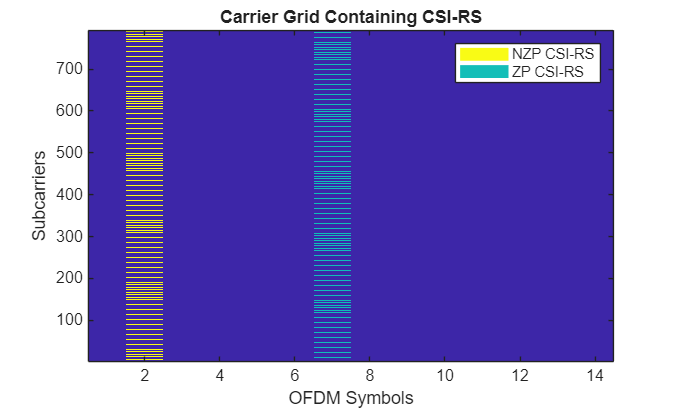

NRB = 66; % no. RBs
SCS = 60; % kHz
ofdmInfo = nrOFDMInfo(NRB,SCS);
pilot_type = "CSI-RS"; % or "DM-RS"
% [txWaveform, carrier, dmrsSymbols, dmrsIndices] = wave_gen(NRB, SCS); %--DM-RS
[txWaveform, carrier, csirsSymbols, csirsIndices] = wave_gen(NRB, SCS, pilot_type, 1, 1); % flag-plot =1, N_t=1

tempGrid = complex(zeros([NRB*12, 14]));
tempGrid(csirsIndices) = csirsSymbols;
csirsGrid = tempGrid(:,2); % 792 x 1 

% CSI-RS periodicity is set to 5, so the slots containing CSI-RS are slots 1, 6, 11
CSIRS_period = 5;
CSIRS_first  = 1;
num_slots = 6; % Generate channel over slots 1 to 6. (CSI-RS at slots 1, 6, 11)
                % Slots 1-6 act as the training data
                % Slots 7-11 act as channels in future

OFDM_span = 14*num_slots;     % OFDM symbols
OFDM_persSlot = 14;  % could be 12 in some settings
considerCP = true; 
return_timeDomain = true;
channel_SampleDensity = inf; % default = 64

% SNRdB = 0:5:30; 
SNRdB = 5;  % -25:5:25;
mse_linear_2to5     = zeros(1, length(SNRdB));
mse_linear_1to6     = zeros(1, length(SNRdB));
mse_duplicate_2to5  = zeros(1, length(SNRdB));
nmse_linear_2to5     = zeros(1, length(SNRdB));
nmse_linear_1to6     = zeros(1, length(SNRdB));
nmse_duplicate_2to5  = zeros(1, length(SNRdB));
num_UE = size(h_freq,3)

num_UE = 2048

for idx_SNR = 1: length(SNRdB)
    snr = SNRdB(idx_SNR);
    fprintf('SNR: %d / %d', snr, SNRdB(end));
    SNR = 10^(snr/10); % Calculate linear SNR
    N0 = 1/sqrt(2*double(ofdmInfo.Nfft)*SNR); % simParameters.NRxAnts = 1

    H_true = h_freq;    % complex value - symbol (OFDM_span) x subc x num_UE

    H_equalized_1 = zeros(OFDM_persSlot,NRB*12,num_UE);  % equalized (LS) channel of slot containing first CSI-RS (slot 1)
                                                         % num_symbol_perSlot (14) x subc x num_UE
    H_equalized_6 = zeros(OFDM_persSlot,NRB*12,num_UE);  % equalized (LS) channel of slot containing second CSI-RS (slot 2)
                                                         % num_symbol_perSlot (14) x subc x num_UE
    H_linear_1    = zeros(OFDM_persSlot,NRB*12,num_UE);  % linear interpolated channel within slot 1
    H_linear_6    = zeros(OFDM_persSlot,NRB*12,num_UE);
    
    H_linear_1to6 = zeros(OFDM_persSlot*6,NRB*12,num_UE);  % linear interpolation across slots 1-6
    H_linear_2to5 = zeros(OFDM_persSlot*6,NRB*12,num_UE);
    H_duplicate_2to5 = zeros(OFDM_persSlot*6,NRB*12,num_UE);
    H_equalized_1_6 = zeros(2,NRB*12,num_UE); % 3 x subcs
    H_linear_1_6     = zeros(2,NRB*12,num_UE); % 3 x subcs


    idx_UE = 1;


    for idx_point = 1:num_UE    

        H_true_n = H_true(:,:,idx_UE).'; % subc x num_symb (792x84)
        %
        rxGrid_1 = zeros(NRB*12, 14); % slot 1 
        rxGrid_6 = zeros(NRB*12, 14); % 792 x 14
        rxGrid_1(:,2) = H_true_n(:,2) .* csirsGrid;  % corresponding CSI-RS at slot 1
        rxGrid_6(:,2) = H_true_n(:,72).* csirsGrid;  % corresponding CSI-RS at slot 6

        % Add noise
        rxGrid_1(:,2)  = awgn(rxGrid_1(:,2),snr,'measured');
        rxGrid_6(:,2)  = awgn(rxGrid_6(:,2),snr,'measured');
        
        % Least Square and then Linear Interpolation
        [H_equalized_n_1, H_linear_n_1] = Lin_Interpolate(rxGrid_1, csirsIndices, csirsSymbols); % subcs x 14
        [H_equalized_n_6, H_linear_n_6] = Lin_Interpolate(rxGrid_6, csirsIndices, csirsSymbols); 
        % [H_equalized_n_11, H_linear_n_11] = Lin_Interpolate(rxGrid_11, csirsIndices, csirsSymbols); 
        
        % to be saved
        H_equalized_n_1_6 = extract_non0({[H_equalized_n_1, H_equalized_n_6]}); % subcs x 2
        H_linear_n_1_6 = extract_non0({H_linear_n_1, H_linear_n_6}); % subcs x 2
       
        % to be saved
        H_equalized_1_6(:,:,idx_UE) = H_equalized_n_1_6.'; % 2 x subcs
        H_linear_1_6(:,:,idx_UE) = H_linear_n_1_6.'; % 2 x subcs
        

        if (mod(idx_UE,200)==0) || (idx_UE==num_UE)
            fprintf('UE no %d / %d \n', idx_UE, num_UE);
        end
        
        idx_UE = idx_UE + 1;
    % end of UEs loop
    end


    save_folder =  ['generatedChannel/ver', num2str(idxFolder),'_/'];  
    if ~exist(save_folder, 'dir')
        mkdir(save_folder);
    end
    save([save_folder, '/', 'sionnaTrue.mat'], ...
                                    'H_linear_1_6',...   % 2 x subcs x nUE
                                    'H_equalized_1_6',... % 2 x subcs x nUE
                                    'H_true',...  
                                    '-v7.3');

% end of SNR loop
end

SNR: 5 / 5

figure
imagesc(real(H_linear_1_6(:,:,3))')
i =3;
figure
imagesc(real(h_freq(:,:,i))')
xlabel('Symbol')
ylabel('Subcarrier')
title('Real part of channel')
colorbar
figure
imagesc(abs(h_freq(:,:,i))')
xlabel('Symbol')
ylabel('Subcarrier')
title('Absolute of channel')
colorbar